# Part 4: Problem set

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

 For this problem set, you will look at a new blood smear image of blood that contains the [parasite Plasmodium vivax](https://www.cdc.gov/dpdx/malaria/index.html). This is a species of parasite that can cause malaria in humans. When the parasite is in the trophozoite, or growing stage, the parasite can be seen in the red blood cells. These parasites make the red blood cells look increasingly like amoebas (less round!). In the image, the infected cell is more amoeboid and the parasite can be seen within the cell as a purple splotch [1]: 

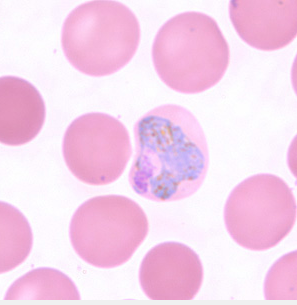

We will remove the infected cell from the image and then count the number of uninfected cells we see. 

## Let's set everything up: 

addpath("images")
cellsP1 = imread("Pv_troph_thinE.jpg");
imshow(cellsP1)

## Problem 1:

Use the 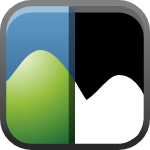 **Color Thresholder** app to separate the pink cells from the purple cell and the background (hint: **YCbCr** colorspace works well). Select 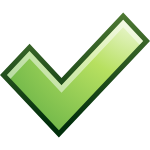**Export**, **Export Images** to export your mask to the workspace. 

## Problem 2: 

Clean up the mask you just exported. Use `bwareaopen()` to remove splotches (*Hint:* to see how good of a job you are doing removing those splotches, display the new mask using` imshow()` or utilize `imshowpair()` with the "`montage"` option to compare the exported mask and the new mask). 

Use `imfill()` with the` "holes"` option to fill the holes or fill the holes in the 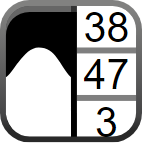 **Image Region Analyzer **app. Use `imshow()` or `imshowpair()` again to display your new, cleaned-up mask. 

## Problem 3: 

Find, visualize, and count the circles in your cleaned-up mask. How many healthy cells do we see on this slide?

First, use `imtool()` to measure radii in your image:

Then, find the circles in your image using `imfindcircles()`.  After finding the circles in your image, create an image that shows the circles plotted on top of your original masked image: 

Count the number of circles found: 

 How many cells did you find? Are any cells that you can see in the image not identified as circles? 

  If you want to catch a few more of the cells that are along the edge of the image, you can try adjusting the "Sensitivity" option in imfindcircles() and re-running the section. Is there a way to catch the cells at the edges of the window?

## References 

[1] Centers for Disease Control and Prevention. (2020). Malaria. Retrieved from [https://www.cdc.gov/dpdx/malaria/index.html](https://www.cdc.gov/dpdx/malaria/index.html)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)